# Multiloop Control Design for VTOL Drone in Fixed Wing Flight

This example shows how to tune the controller gains for reference tracking of attitude, altitude, and airspeed of a VTOL aircraft in fixed wing configuration. 

Copyright 2025 The MathWorks, Inc.

To return to the main page within this repository, [click here](matlab:web('EVTOLDesignOverview.html')).

## Setup Fixed Wing Configuration

Set the aircraft in the fixed wing configuration.

SetupPlant;

Initialized VTOL model.
Enabled hover guidance mission.


SetupFixedWingConfiguration;

## Setup Guidance Test Bench for Fixed Wing.

You can use the guidance algorithms in UAV Toolbox software as a guidance test bench to validate VTOL aircraft flying complex missions. 

SetupFixedWingGuidanceMission;

Enabled fixed-wing guidance mission.


Next, fly the mission with initial controller gains.

Open and run the `VTOLTiltrotor.slx` model. To visualize the trajectory during the simulation, open the UAV Animation block inside the Visualization subsystem.

open_system(mdl);
out = sim(mdl);

The aircraft takes off and navigates through a few waypoints before reducing altitude and then orbiting around a reference point.

## Analyze Tracking and Control Performance with Untuned Gains

After executing the fixed wing mission, you can visualize the output aircraft state to evaluate the control design performance. 

Compare the commanded altitude and airspeed with the output altitude and airspeed for the entire duration of the mission. The plots below show that there is a significant steady state error in both measurements, and the aircraft takes a long time to reduce its altitude.

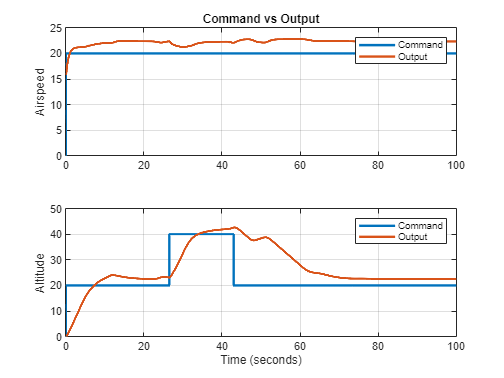

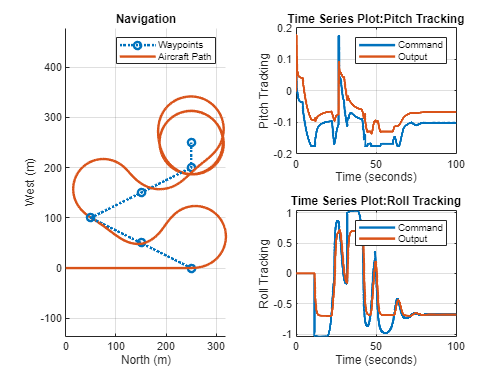

exampleHelperPlotFixedWingControlTrackingResults(out,FixedWingMission)

The third plot shows the navigation metrics of the aircraft as it follows the commanded course. The plots are the aircraft path and the mission waypoints in the XY plane (left), and the comparisons of the pitch and roll angle output with the commanded values (right). The untuned controller is unable to track the reference angles, leading to the aircraft not able to efficiently navigate through the waypoints. The pitch controller performance also causes oscillatory behavior as shown in the altitude tracking plot.

## Automate Tuning of Attitude Controller for Tiltrotor in Fixed Wing

In this step, you use [`systune`](docid:slcontrol_ug#bt9u4gp-1), a fixed-structure tuning method in Simulink® Control Design™ software, to adjust the controller gains based on design goals specified for multiple feedback loops of the `VTOLTiltrotor` model. For more information about the basic tuning and validation workflow, see [Automated Tuning Workflow](docid:slcontrol_ug#bt_v470).

The Fixed Wing Controller subsystem in the model contains an inner loop Attitude Controller subsystem that tracks the roll and pitch angles. The outer loops of Airspeed-Altitude Controller and Lateral Guidance Logic subsystems compute the pitch and roll angular set points for the inner loop controller. In this example, you use programmatic tuning for PID controllers in the attitude, altitude, and airspeed loops shown in the highlighted subsystems in the following diagram.

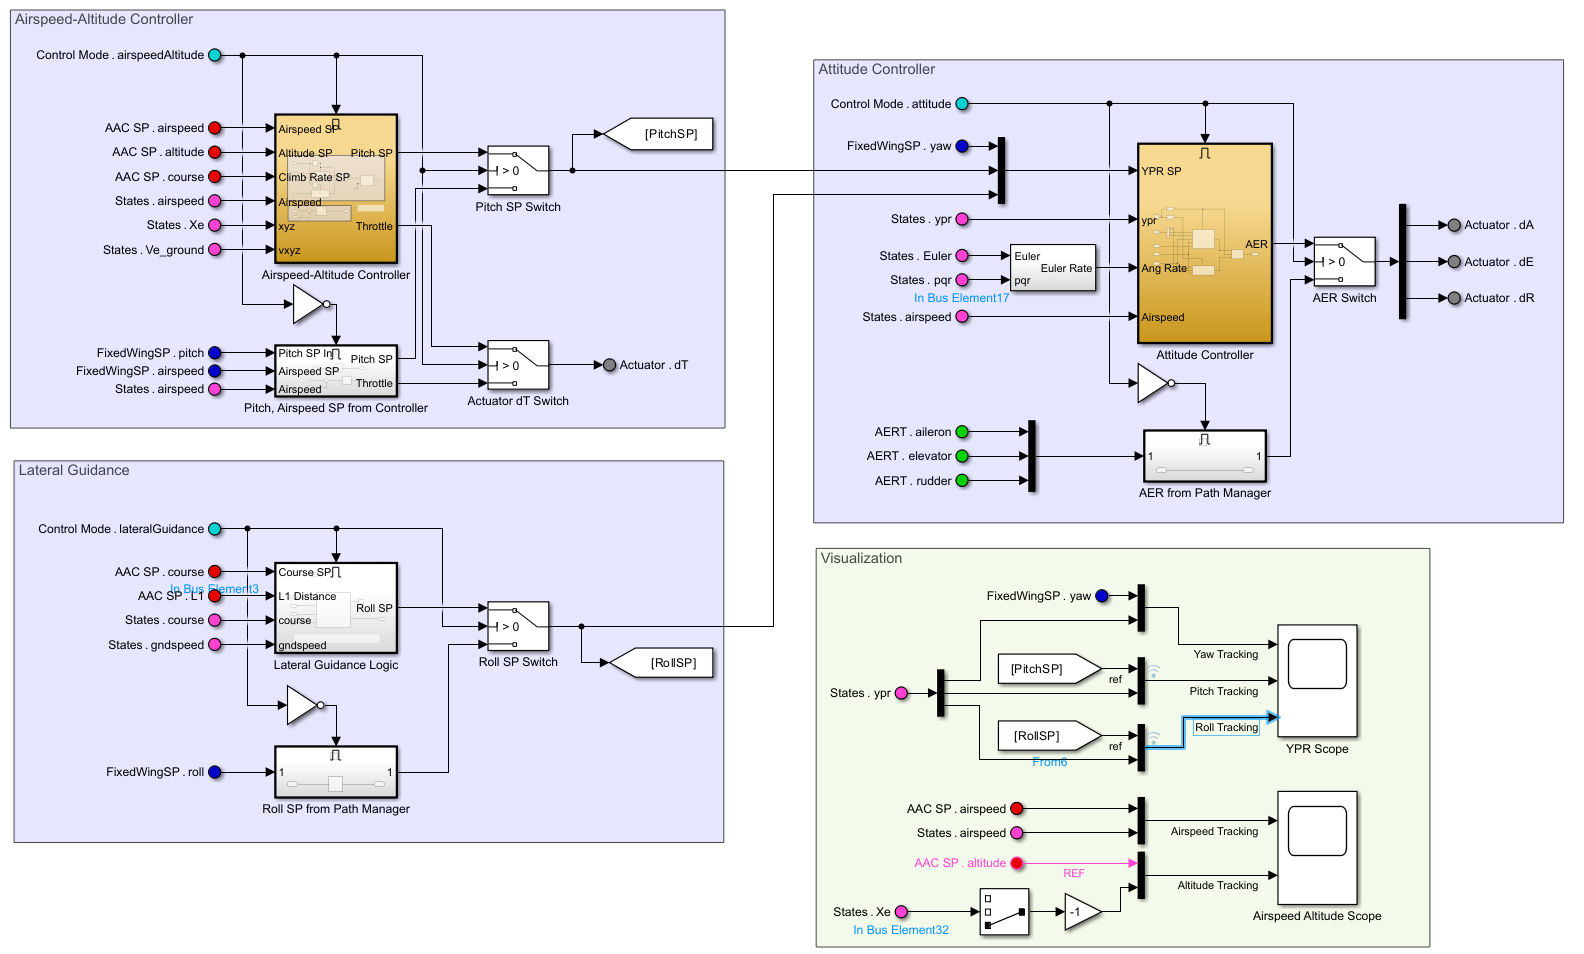 

The desired response for the different loops is based on analysis that mentions settling time for the airspeed, altitude and roll controllers [4]. To obtain a faster response for the inner loops, you tune the pitch and roll control loop to a higher bandwidth.

### Define Interface for Tuning

To tune the aircraft controllers, specify the angle setpoints, measured outputs, and the loop gain locations for pitch and roll loops as the linear analysis points. Create an [`slTuner`](docid:slcontrol_ug#bt_7xj5-1) object, the interface for tuning of Simulink® models, using the controller blocks to tune and the analysis points as input. For tuning, the interface linearizes the model around an initial condition at which the aircraft is cruising in steady state with a fixed velocity.

To specify the analysis points and blocks to tune for pitch and roll loops, run the `exampleHelperSetupFixedWingControlTuning_Attitude` script.

exampleHelperSetupFixedWingControlTuning_Attitude;

mdl = 'EVTOLTiltrotor'

Create the `slTuner` object.

options=slTunerOptions('AreParamsTunable',false,'RateConversionMethod','tustin');
attitudeTuner=slTuner(mdl,tunedBlocks,analysisPoints,options);
attitudeTuner.Ts=0.005;
attitudeTuner.OperatingPoints=5;

### Create Tuning Goals for Pitch and Roll Controllers

Use loop-shaping design to create a desired open-loop response of an integrator with bandwidth of 10 rad/s for roll and pitch control loops. This helps track the reference inputs with zero steady state error, while attenuating inputs with frequencies that exceed the bandwidth.

Define bandwidth.

wcRoll = 20;
wcPitch = 15;

Create the loop-shaping goals for the roll and pitch loops using [TuningGoal.LoopShape](docid:control_ref#bs4eo8s-1).

rollLoopShape = TuningGoal.LoopShape({rollOpenLoopLocation}, wcRoll);
rollLoopShape.Name = 'Roll Loop Shape';
pitchLoopShape = TuningGoal.LoopShape({pitchOpenLoopLocation}, wcPitch);
pitchLoopShape.Name = 'Pitch Loop Shape';

Visualizing the loop shaping goal. The plot shows the singular values of the desired target loop shape. The green region shows the constraints on the inverse sensitivity function as minimum low-frequency loop gain, and the red region marks the complementary sensitivity as maximum high-frequency loop gain.

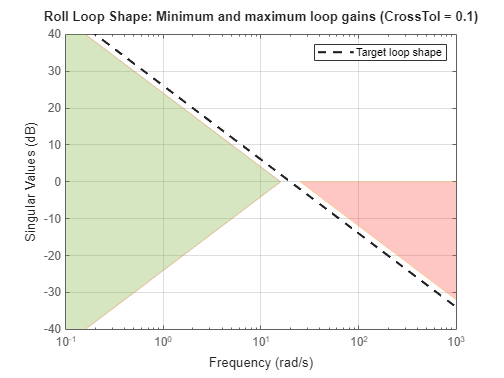

viewGoal(rollLoopShape);

Create the tuning goals to match the step response to a desired first order response with a time constant of 0.5 seconds for pitch and roll (see [TuningGoal.StepTracking](docid:control_ref#bt6tuje-1)). These time constants map to the settling times mentioned in [4]. To compute the linearized closed-loop response, compute the open loop response of the outer loops that compute the set points for pitch and roll.

% Define time constant
tauRoll = 1/wcRoll;
tauPitch = 1/wcPitch;
% Roll Loop
rollStepTracking = TuningGoal.StepTracking({rollAngleInput},{rollAngleOutput}, tauRoll, 10);
rollStepTracking.Openings = [{rollAngleInput}; {pitchAngleInput}];
rollStepTracking.Name = 'Roll Step Tracking';

% Pitch Loop
pitchStepTracking = TuningGoal.StepTracking({pitchAngleInput},{pitchAngleOutput}, tauPitch, 10);
pitchStepTracking.Openings = [{rollAngleInput}; {pitchAngleInput}];
pitchStepTracking.Name = 'Pitch Step Tracking';

The visualization shows the desired step response of the closed-loop system. 

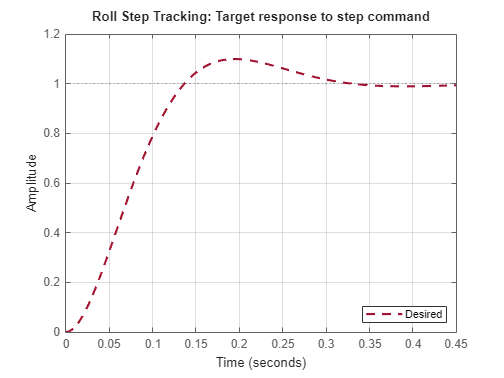

viewGoal(rollStepTracking);

### Tune Controller Gains and Analyze Results

Use `systune` to tune the gains based on the defined soft goals.The `systune` function performs a multi-objective optimization to meet step tracking and frequency response requirements. Tuning for step tracking and loop shape tuning goals enables the controller to achieve a good tracking performance with a desired bandwidth that rejects of high frequency disturbance and noise. 

% Options
options = systuneOptions();
options.Display = 'final';
% options.RateConversionMethod = 'tustin';
% Tune
attitudeTuner_Tuned= systune(attitudeTuner,[rollLoopShape; rollStepTracking; pitchLoopShape; pitchStepTracking], options);

Final: Soft = 3.6, Hard = -Inf, Iterations = 34


The best achieved soft constraint value of slightly greater than 1 indicates that the solution nearly satisfies all requirements. A closer inspection of the tuning goal plots shows that the multi-objective optimization returns a solution that matches the open loop shape and is slightly higher than desired bandwidth, as well as the closed-loop step response. This is considered acceptable for the inner loop performance as it nearly meets al the requirements of minimum and maximum loop gains and the overall objective is close to 1. 

The warning indicates the presence of modeling artifacts that do not affect the tuning results and the performance of the controller.

Visualize the tuned results.

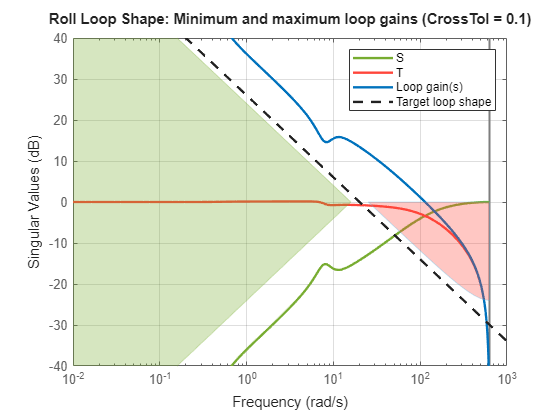

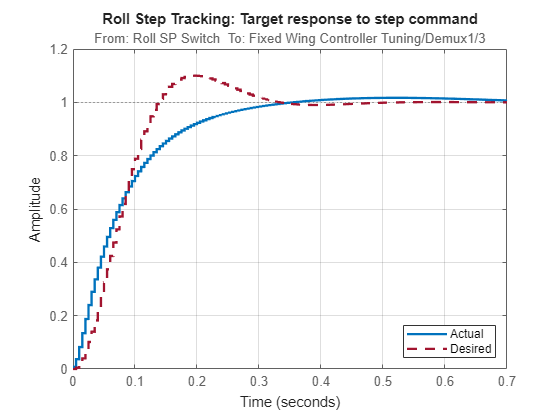

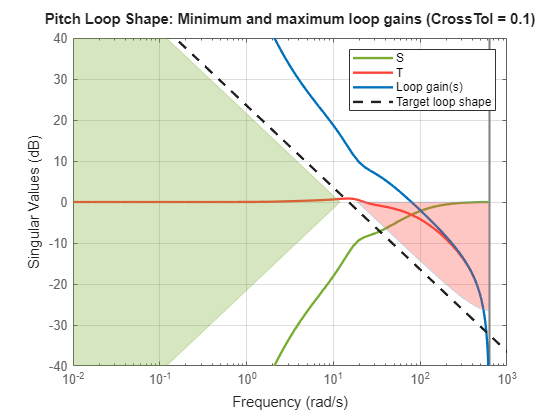

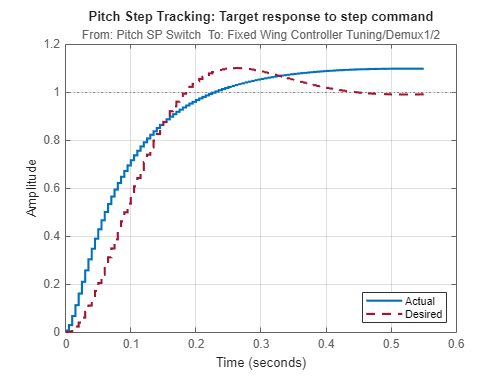

exampleHelperViewTuningGoal([rollLoopShape,rollStepTracking,pitchLoopShape,pitchStepTracking],attitudeTuner_Tuned);

### Update Parameters

Update the parameters with the tuned values. In this example, the `exampleHelperWriteBlockValue_Attitude` function updates the variable values in the MATLAB® workspace that the controller blocks uses in the model. This function updates the `FWControlParams` struct in the workspace with the new control gains.

FWControlParams=exampleHelperWriteBlockValue_FwAttitude(attitudeTuner_Tuned,FWControlParams);

## Automate Tuning of Airspeed-Altitude Controller for Tiltrotor in Fixed Wing

In this section, you tune the airspeed and altitude controllers using `systune` and `slTuner`, similar to tuning the attitude loops in the preceding section.

### Define Interface for Tuning

Specify analysis points and blocks to tune for altitude and airspeed loops.

exampleHelperSetupFixedWingControlTuning_AltitudeAirspeed;

mdl = 'EVTOLTiltrotor'

Create the `slTuner` object.

options = slTunerOptions('AreParamsTunable',false);
altitudeAirspeedTuner = slTuner(mdl,tunedBlocks,analysisPoints,options);
altitudeAirspeedTuner.Ts = 0.005;
altitudeAirspeedTuner.OperatingPoints=2;


### Create Tuning Goals for Altitude and Airspeed Controllers

Create the desired loop shapes of an integrator with bandwidth of 1 rad/s for altitude control loop and 10 rad/s for airspeed control.

% Altitude Loop
Wc = 2;
altitudeLoopShape = TuningGoal.LoopShape({altitudeOpenLoopLocation},Wc);
altitudeLoopShape.Name = 'Altitude Loop Shape';
% Airspeed Loop
Wc = 10;
airspeedLoopShape = TuningGoal.LoopShape({airspeedOpenLoopLocation},Wc);
airspeedLoopShape.Name = 'Airspeed Loop Shape';

Create step tracking goals using first order response with time constants of 1 seconds for altitude and 0.1 seconds for airspeed. 

% Altitude Loop
Tau = 1/2;
altitudeStepTracking = TuningGoal.StepTracking({altitudeInput},{altitudeOutput},Tau);
altitudeStepTracking.Name = 'Altitude Step Tracking';
% Airspeed Loop
Tau=0.1;
airspeedStepTracking = TuningGoal.StepTracking({airspeedInput},{airspeedOutput},Tau);
airspeedStepTracking.Name = 'Airspeed Step Tracking';

### Tune Controller Gains and Analyze Results

Use `systune` to tune the gains based on the defined soft goals.

% Options
options = systuneOptions();
options.Display = 'final';

% Tune
[altitudeAirspeedTuner_Tuned] = systune(altitudeAirspeedTuner,[altitudeLoopShape; altitudeStepTracking; airspeedLoopShape; airspeedStepTracking],options);

Final: Soft = 2.14, Hard = -Inf, Iterations = 32


Compare the result to the tuning goals. The plots show that the tuned controllers are able to provide the required bandwidth and step tracking time response.

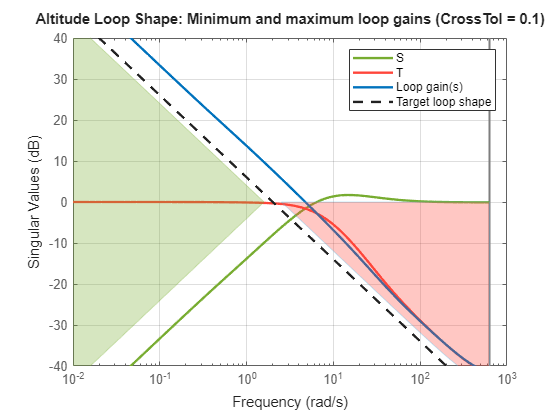

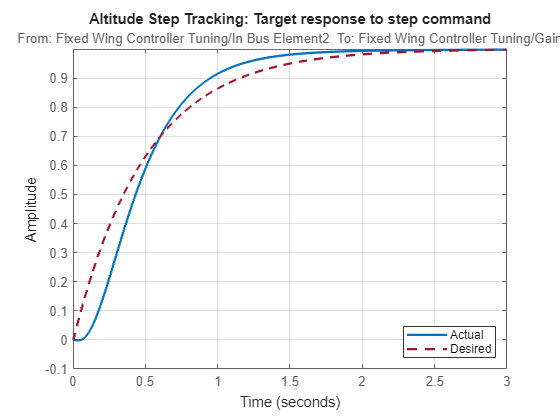

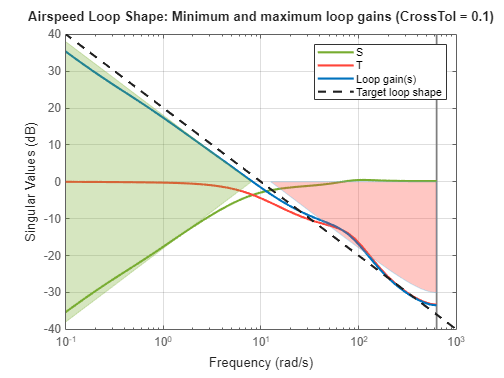

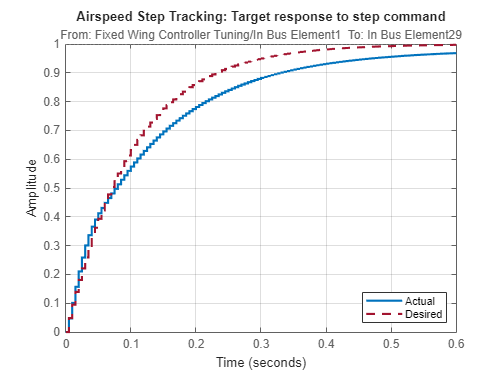

exampleHelperViewTuningGoal([altitudeLoopShape; altitudeStepTracking; airspeedLoopShape; airspeedStepTracking],altitudeAirspeedTuner_Tuned);

### Update Parameters

Update the parameters with the tuned values. In this example, the `exampleHelperWriteBlockValue_AltitudeAirspeed` function updates the variable values in the MATLAB® workspace used by the con

troller blocks in the model. 

FWControlParams=exampleHelperWriteBlockValue_AltitudeAirspeed(altitudeAirspeedTuner_Tuned,FWControlParams);

## Analyze Tracking and Control Performance with Tuned Gains

TestMode = 1;
TuningMode = 0;
guidanceType=1;

out = sim(mdl);

The altitude and airspeed plots show that the outputs converge in a shorter time without any steady state error and oscillations.

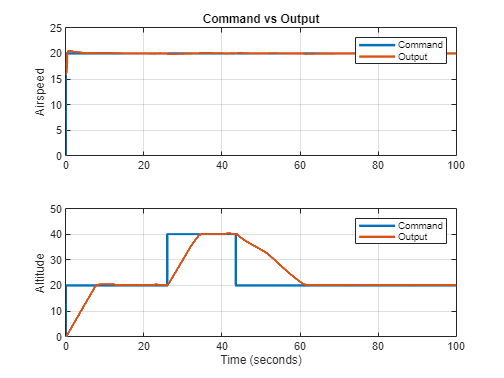

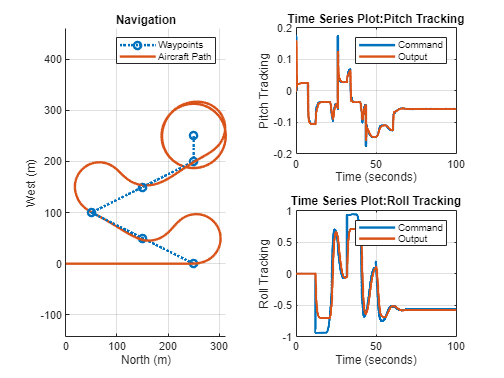

exampleHelperPlotFixedWingControlTrackingResults(out,FixedWingMission);

The comparison of pitch and roll angles shows an improved tracking with a faster response. Note that the roll tracking is saturated within the roll controller. In conclusion, the aircraft navigates the waypoints more efficiently.

## Summary

This example tuned the control design of a VTOL in fixed wing configuration. Next, design the control system of the transition mode of the VTOL aircraft. 

**References**

[1] N., Pavan. (2020). Design of Tiltrotor VTOL and Development of Simulink Environment for Flight Simulations. 

[2] Mathur, Akshay & Atkins, Ella. (2021). Design, Modeling and Hybrid Control of a QuadPlane.

[3] Ducard, Guillaume Jacques Joseph and Minh-Duc Hua  (2014). Modeling of an unmanned hybrid aerial vehicle.

[4] [Transition from Low- to High-Fidelity UAV Models in Three Stages](https://www.mathworks.com/help/uav/ug/transition-from-low-to-high-fidelity-uav-models.html) - The Mathworks Inc.

*Copyright 2023 The MathWorks, Inc.*